# Problem 7

Part A)

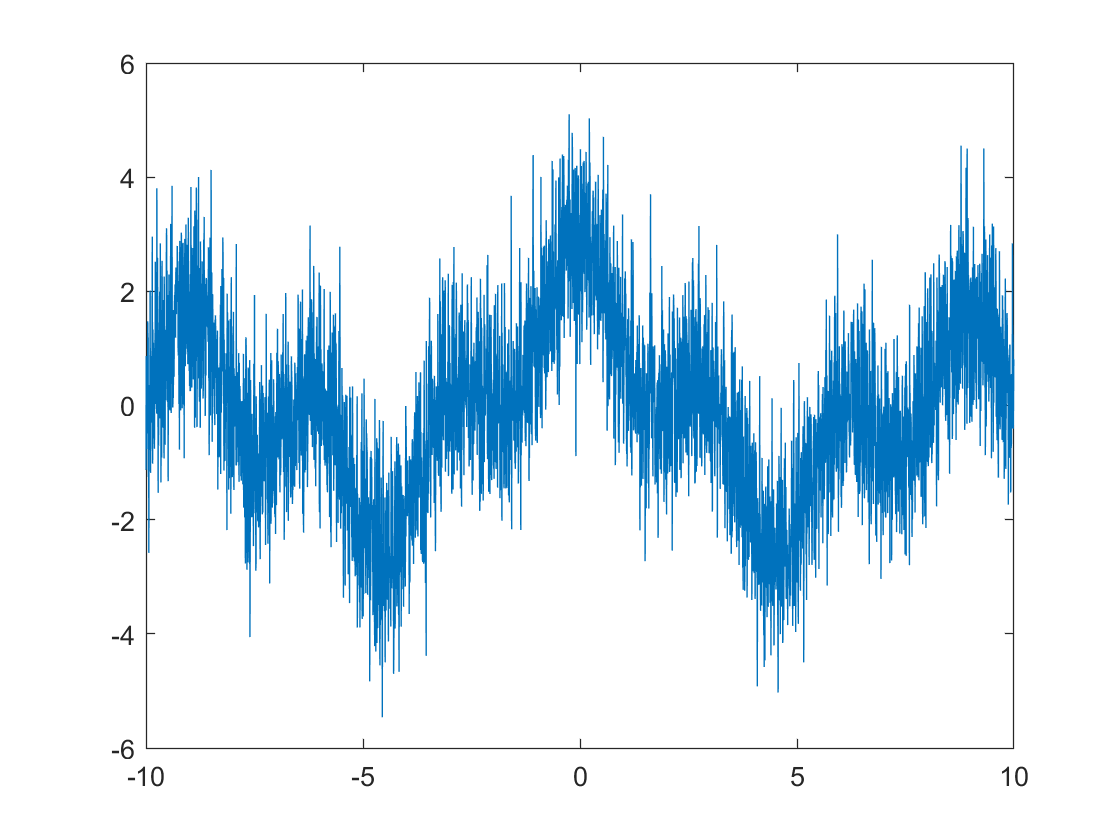

% generate signals
T = 0.005;
Fs = 1/T;
n = -10:T:10-T;
f = (Fs*(0:length(n)-1)/length(n));

x1 = cos(pi*n/6);
x2 = cos(pi*n/4);
x3 = cos(2*pi*n/3);
v = randn(length(n));
v = v(1,:);

x = x1 + x2 + x3 + v;

%plot the output
plot(n, x)

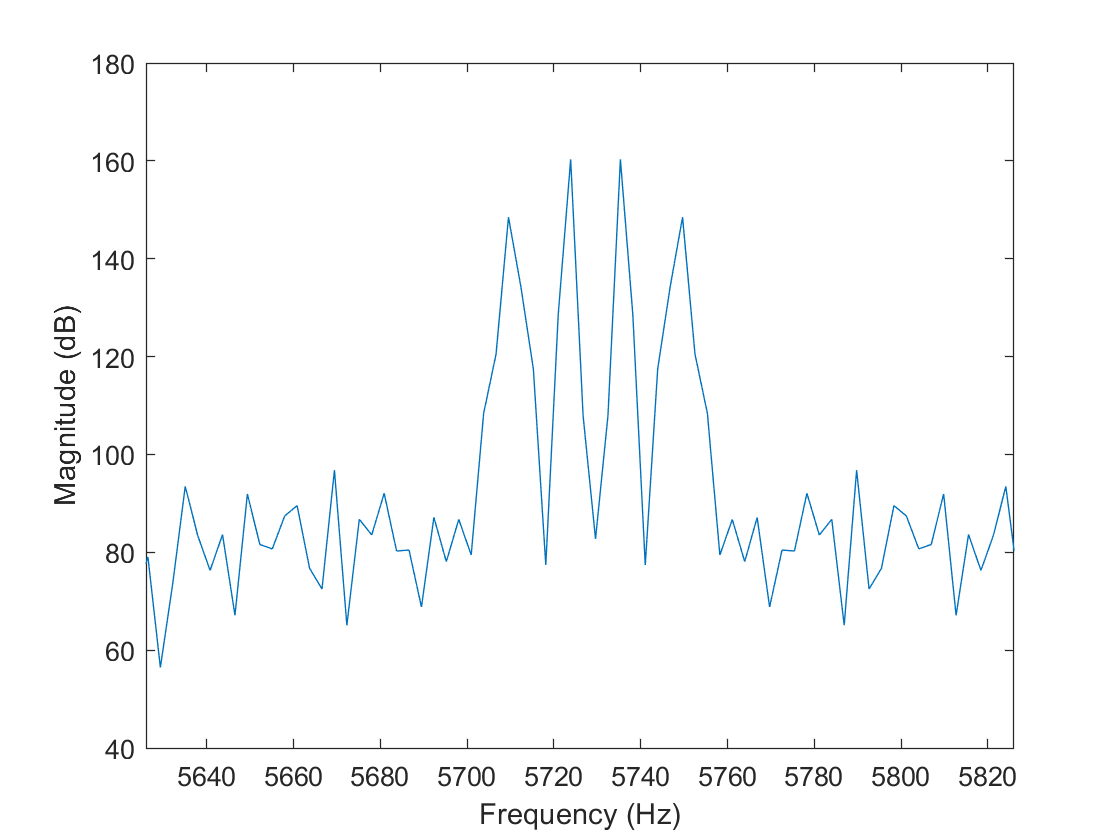

%plot in the frequency domain
X = fft(x);
plot(f*180/pi,20*log(abs(fftshift(X))))
xlabel 'Frequency (Hz)', ylabel 'Magnitude (dB)'
xlim([5726-100, 5726+100])

Create a low pass filter

wp = (pi/4)%omega(indeces(2)) 45hz

wp = 0.7854

wp = 5*pi/180

wp = 0.0873

ws = (2*pi/3)%omega(indeces(3)) 120Hz

ws = 2.0944

ws = 120*pi/180

ws = 2.0944


% get the filter order, frequency banned, whether they're pass or stop, and w
[n,fo,ao,w] = firpmord([wp ws],[1 0],[0.0001 0.01],Fs)

n = 325

fo =          0
    0.0009
    0.0209
    1.0000


ao =      1
     1
     0
     0


w =    100
     1


% calculate the filter
b = firpm(n,fo,ao,w)

b =    -0.0005   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009   -0.0009


% the last step in calculating a filer
[H,w] = freqz(b,1,length(f)/2);
% take the transpose of H so it's oriented correctly
H = H';
% flip and append H so it covers the negative part of the frequency domain too
H = fftshift([fliplr(H) H])/max(H)

H =    0.9676 - 0.2525i   1.0000 + 0.0000i   0.9676 + 0.2525i   0.8723 + 0.4885i   0.7202 + 0.6924i   0.5213 + 0.8506i   0.2889 + 0.9522i   0.0389 + 0.9902i  -0.2111 + 0.9619i  -0.4432 + 0.8698i  -0.6408 + 0.7212i  -0.7899 + 0.5278i  -0.8802 + 0.3052i  -0.9067 + 0.0714i  -0.8696 - 0.1553i  -0.7749 - 0.3573i  -0.6334 - 0.5198i  -0.4595 - 0.6324i  -0.2700 - 0.6898i  -0.0819 - 0.6920i   0.0891 - 0.6443i   0.2304 - 0.5563i   0.3336 - 0.4407i   0.3947 - 0.3112i   0.4148 - 0.1814i   0.3986 - 0.0631i   0.3540 + 0.0349i   0.2908 + 0.1073i   0.2188 + 0.1525i   0.1470 + 0.1721i   0.0826 + 0.1702i   0.0304 + 0.1526i  -0.0074 + 0.1254i  -0.0307 + 0.0946i  -0.0414 + 0.0647i  -0.0425 + 0.0392i  -0.0371 + 0.0198i  -0.0286 + 0.0069i  -0.0196 - 0.0004i  -0.0117 - 0.0033i  -0.0058 - 0.0034i  -0.0022 - 0.0022i  -0.0004 - 0.0007i   0.0001 + 0.0004i   0.0000 + 0.0009i  -0.0002 + 0.0009i  -0.0003 + 0.0005i  -0.0001 + 0.0001i   0.0003 - 0.0002i   0.0006 - 0.0002i


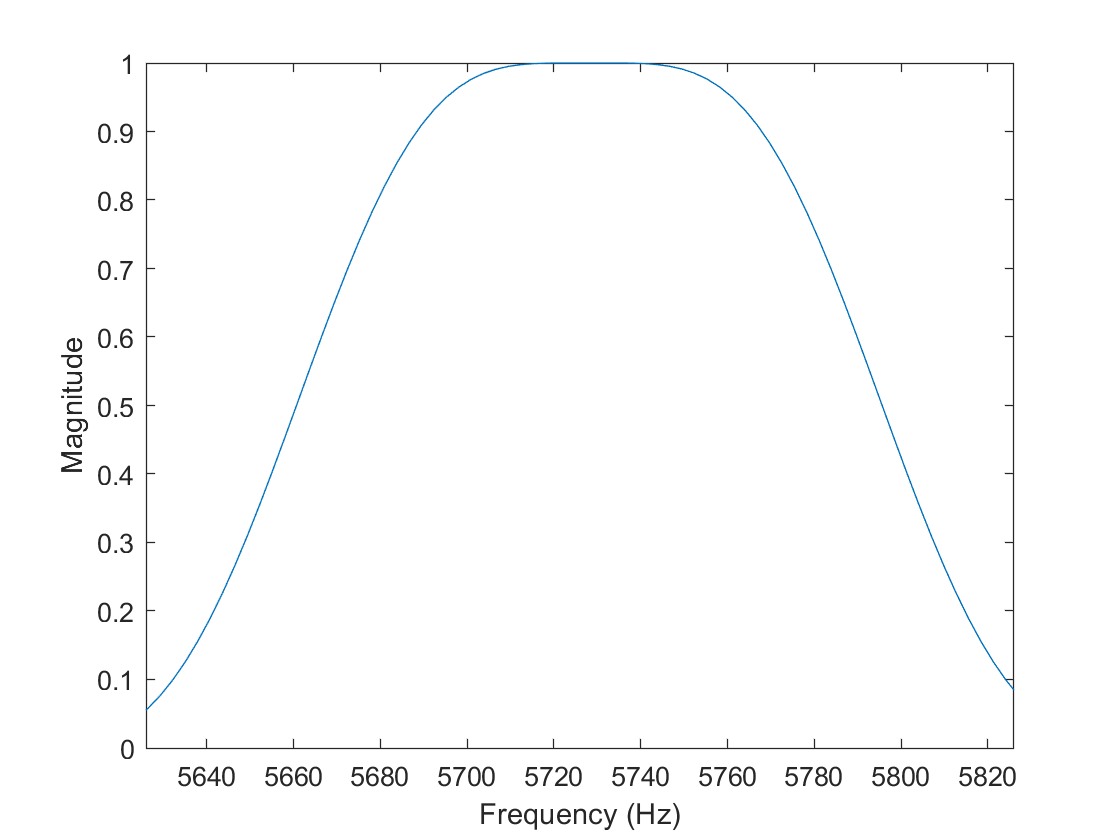

% plot the resulting filter
plot(f*180/pi,abs(fftshift(H)))
xlabel 'Frequency (Hz)', ylabel 'Magnitude'
xlim([5726-100, 5726+100])

Apply the low pass filter and see its result in the time and frequency domain.

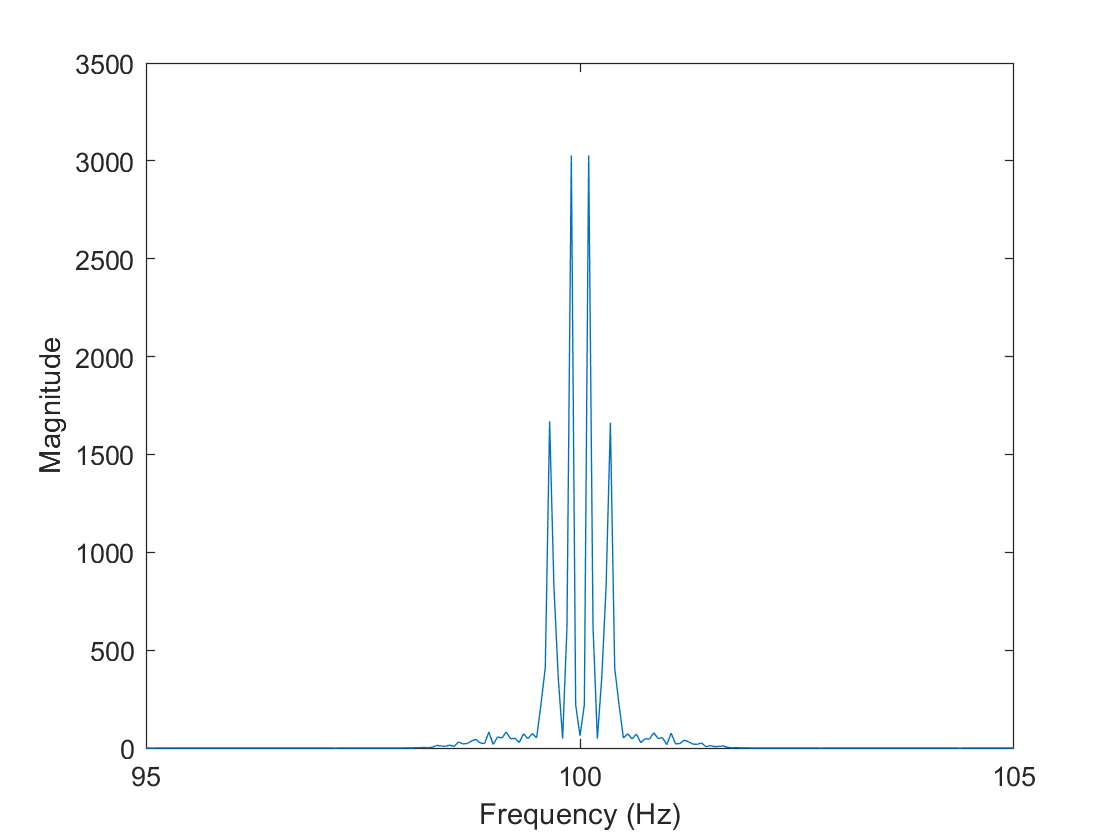

Y = H.*X; % apply the filter to our noisy signal
n = -10:T:10-T;

plot(f, abs(fftshift(Y))) % plot the frequency domain output
xlabel 'Frequency (Hz)', ylabel 'Magnitude'
xlim([100-5, 100+5])

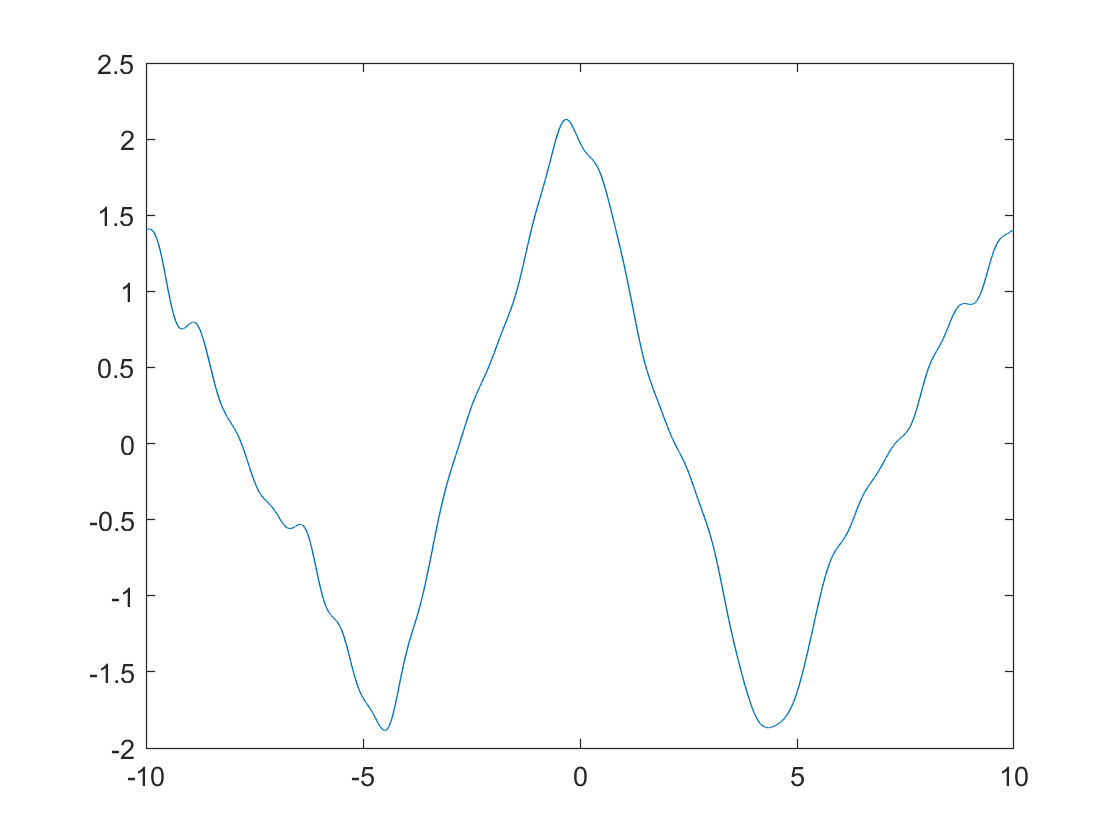

%xlim([5726-100, 5726+100])

% our filtered output
plot(n, ifft(Y)) % the new filtered plot

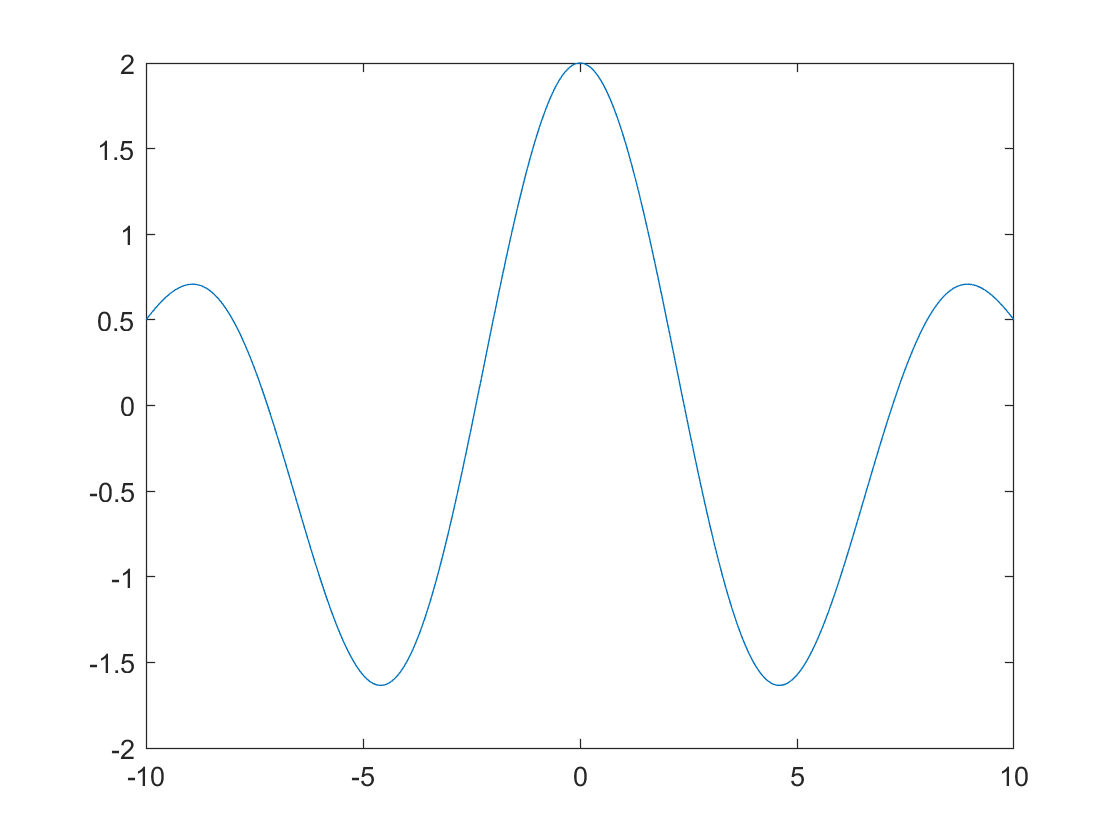

% some other plots for comparison
plot(n, x1 + x2) % the ideal plot

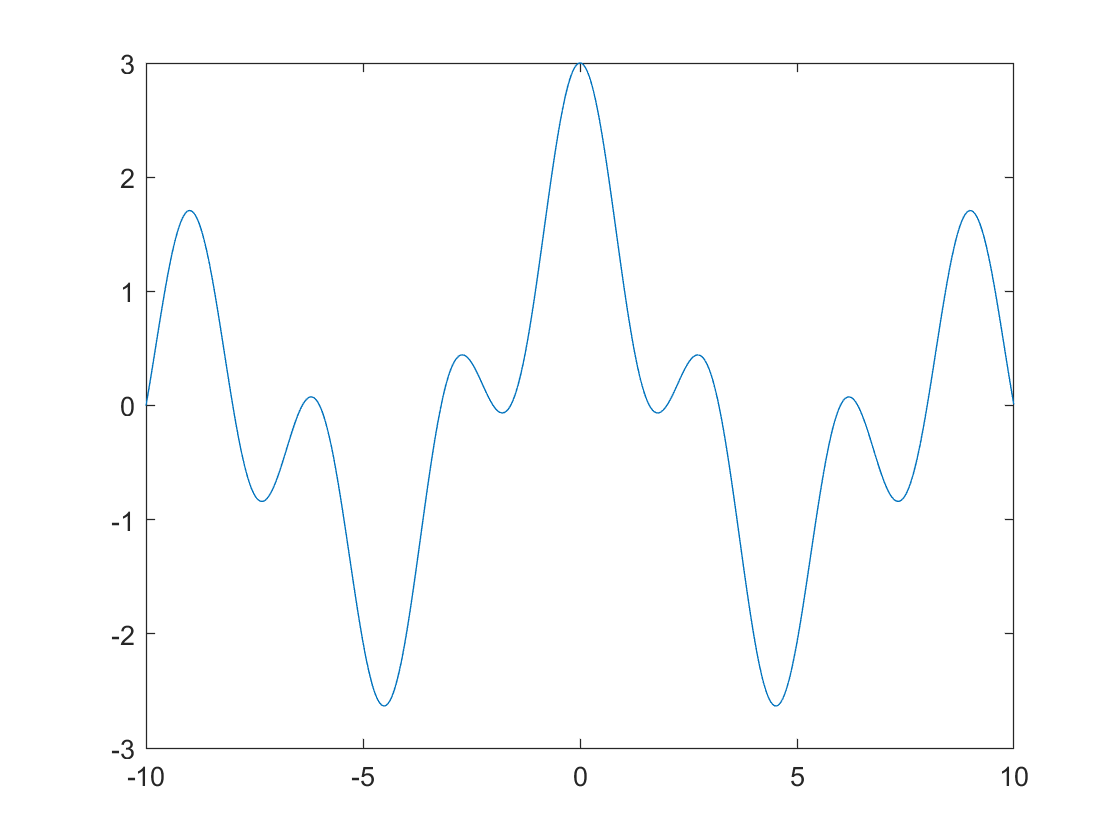

plot(n, x1 + x2 + x3) % the output plot without filtering x3

As can be seen from the final two charts, this filter does a good job at filtering out most of the noise and also recreating the original plot.

#### Part B) Designan FIR high pass filter to extract x3

We will begin by constructing our high-pass filter since all of the other signals have been made.

wp = (pi/4)%omega(indeces(2)) 45hz

wp = 0.7854

wp = 15*pi/180

wp = 0.2618

ws = (2*pi/3)%omega(indeces)) 120Hz

ws = 2.0944

ws = 10*pi/180

ws = 0.1745


% get the filter order, frequency banned, whether they're pass or stop, and w
[n,fo,ao,w] = firpmord([ws wp],[0 1],[0.01 0.01],Fs)

n = 4456

fo =          0
    0.0017
    0.0026
    1.0000


ao =      0
     0
     1
     1


w =      1
     1


% calculate the filter
b = firpm(n,fo,ao,w)

b =     0.0056   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001


% the last step in calculating a filer
[H,w] = freqz(b,1,length(f)/2);
% take the transpose of H so it's oriented correctly
H = H';
% flip and append H so it covers the negative part of the frequency domain too
H = fftshift([fliplr(H) H]/max(H))

H =   -0.0089 - 0.0066i   0.0072 + 0.0110i   0.0001 + 0.0005i  -0.0024 + 0.0171i  -0.0997 + 0.1841i   0.6885 - 0.5993i  -0.9173 + 0.3433i   1.0000 + 0.0000i  -0.9173 - 0.3433i   0.7501 + 0.6530i  -0.4698 - 0.8674i   0.1360 + 0.9776i   0.2168 - 0.9698i  -0.5358 + 0.8213i   0.8042 - 0.5921i  -0.9405 + 0.2668i   0.9962 + 0.0816i  -0.8859 - 0.4169i   0.6953 + 0.7130i  -0.3967 - 0.9010i   0.0559 + 0.9876i   0.2946 - 0.9469i  -0.6020 + 0.7761i   0.8490 - 0.5240i  -0.9595 + 0.1893i   0.9864 + 0.1626i  -0.8484 - 0.4874i   0.6354 + 0.7680i  -0.3215 - 0.9294i  -0.0249 + 0.9899i   0.3705 - 0.9190i  -0.6638 + 0.7249i   0.8886 - 0.4527i  -0.9719 + 0.1104i   0.9698 + 0.2425i  -0.8056 - 0.5549i   0.5707 + 0.8175i  -0.2445 - 0.9523i  -0.1056 + 0.9848i   0.4442 - 0.8855i  -0.7207 + 0.6684i   0.9225 - 0.3787i  -0.9776 + 0.0307i   0.9468 + 0.3209i  -0.7577 - 0.6188i   0.5021 + 0.8613i  -0.1660 - 0.9692i  -0.1856 + 0.9727i   0.5151 - 0.8465i  -0.7727 + 0.6072i


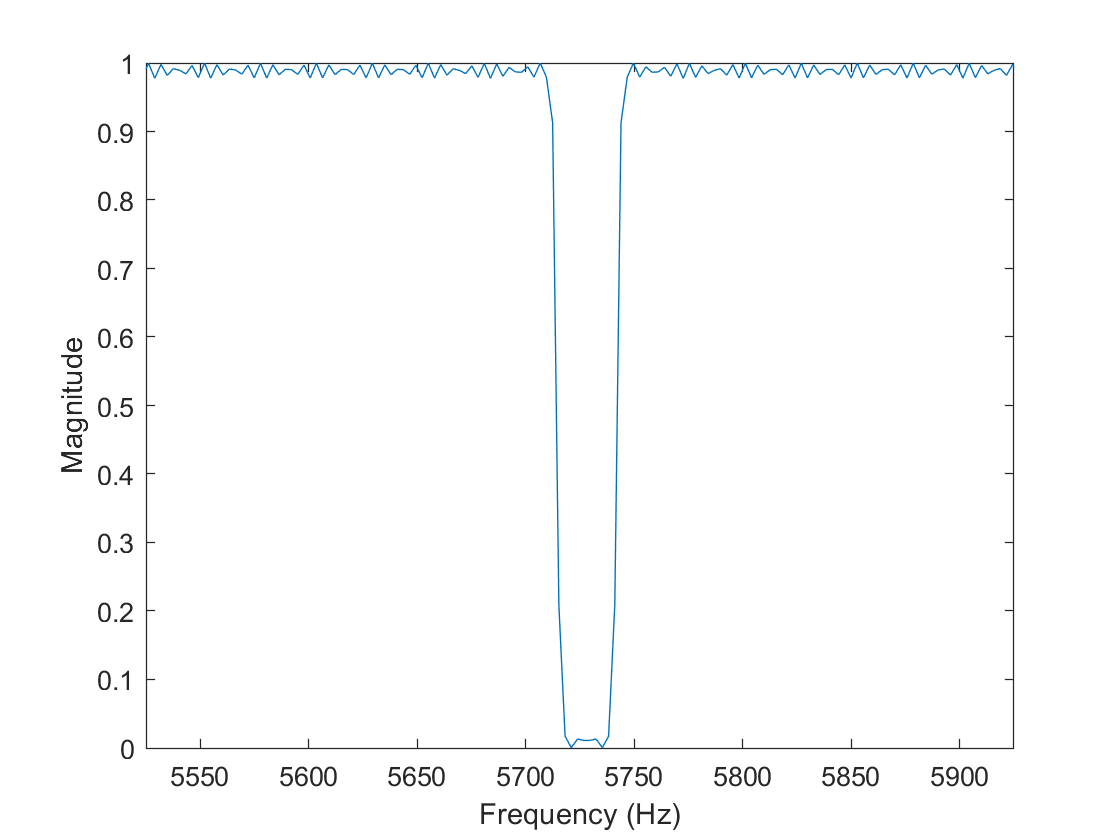

% plot the resulting filter
plot(f*180/pi,abs(fftshift(H)))
xlabel 'Frequency (Hz)', ylabel 'Magnitude'
xlim([5725-200, 5725+200])

Now we will apply this filter to our input signal

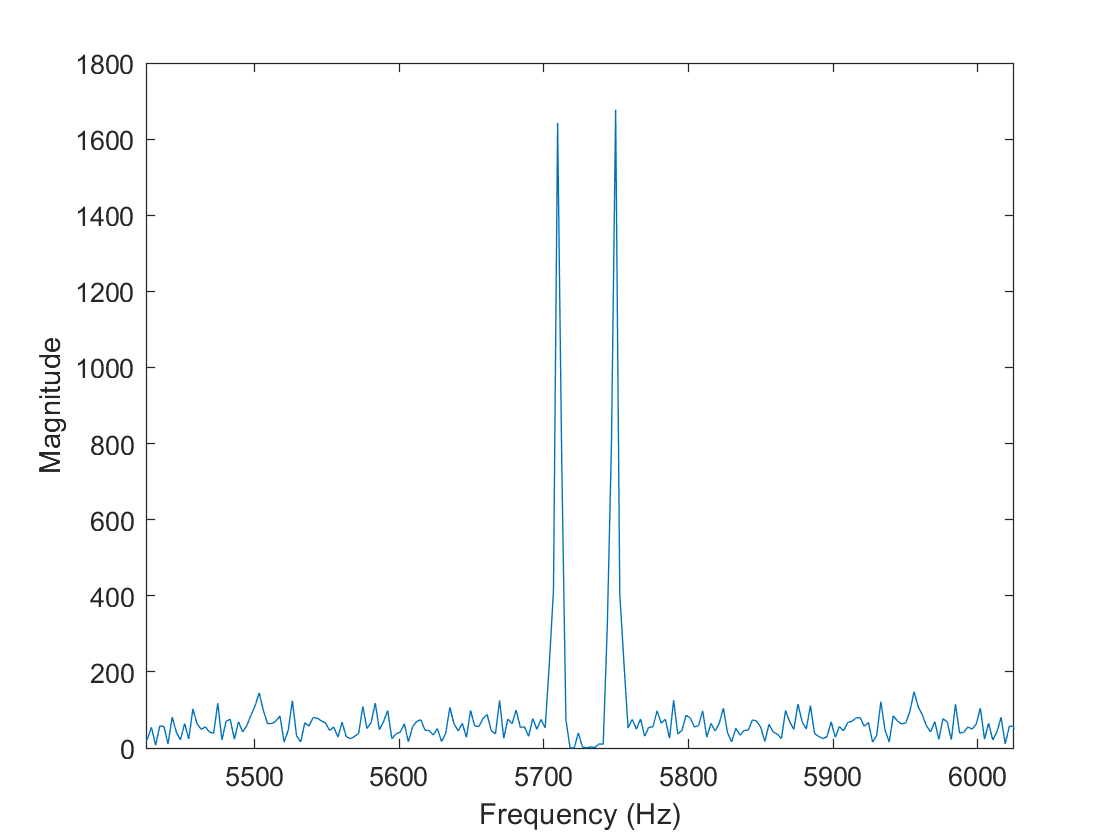

Y = H.*X; % apply the filter to our noisy signal
n = -10:T:10-T;

plot(f*180/pi, abs(fftshift(Y))) % plot the frequency domain output
xlabel 'Frequency (Hz)', ylabel 'Magnitude'
xlim([5725-300, 5725+300])

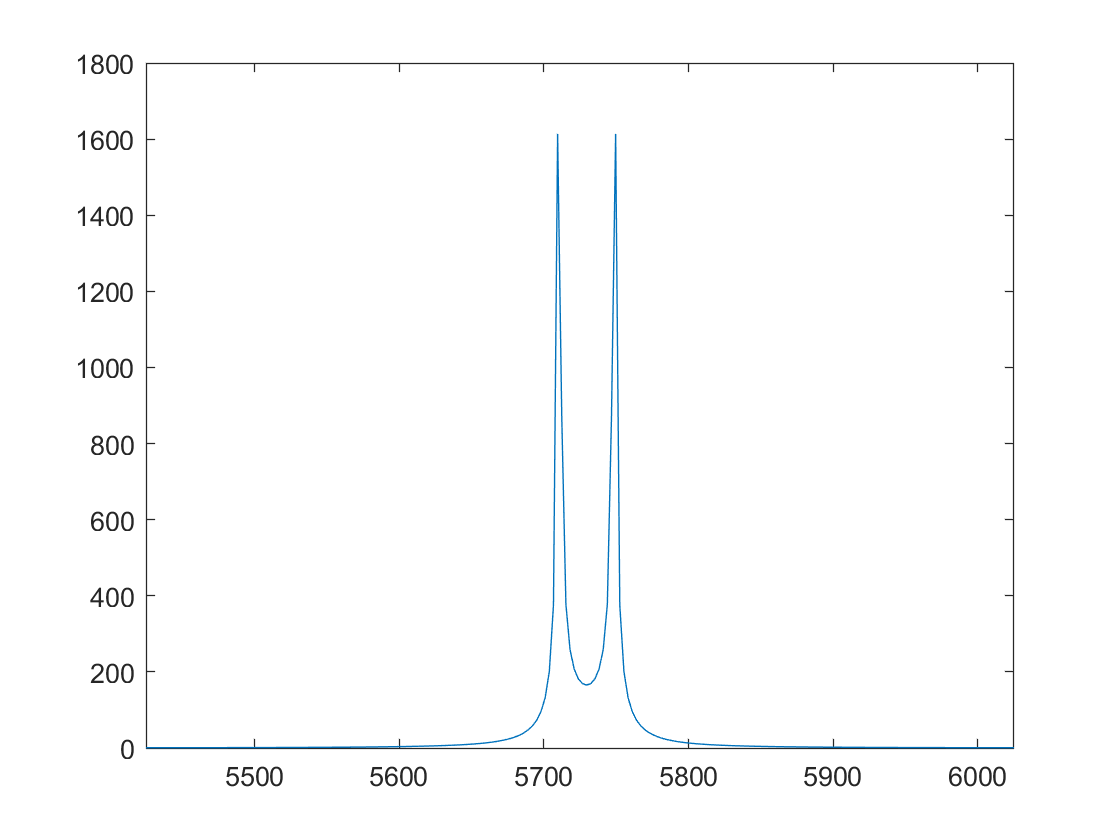


plot(f*180/pi, abs(fftshift(fft(x3))))
xlim([5725-300, 5725+300])

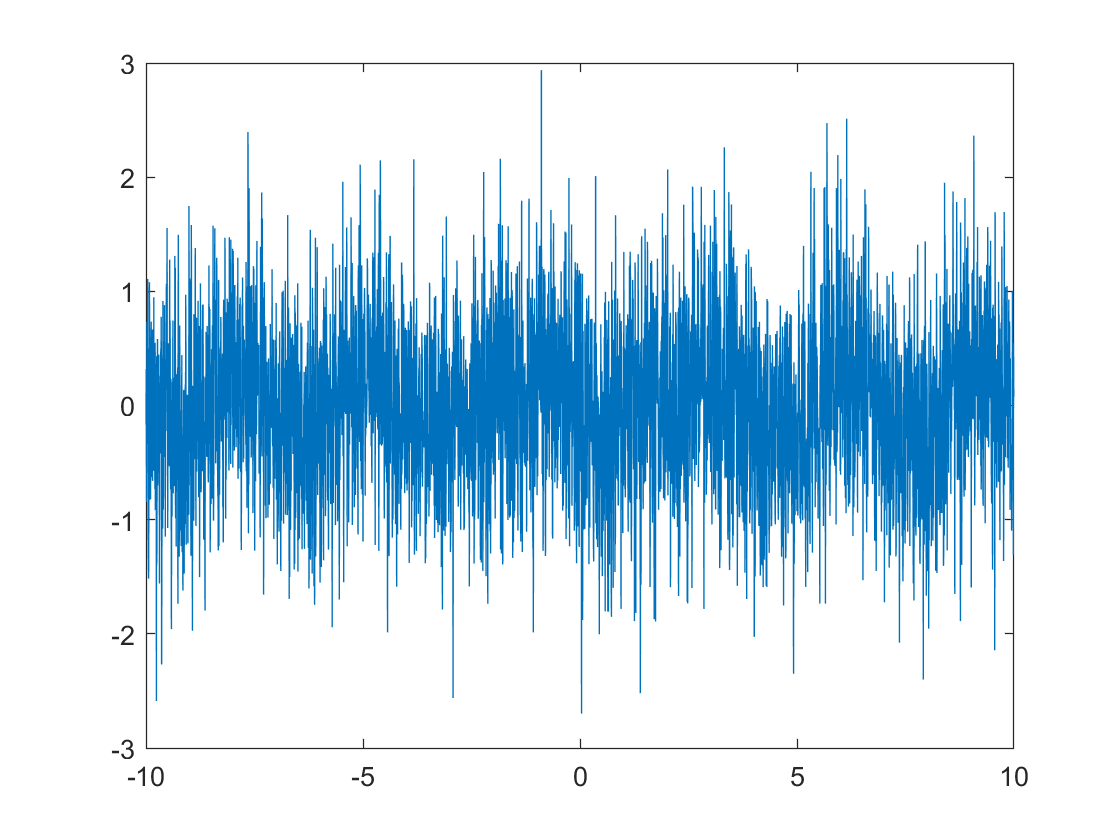


% our filtered output
plot(n, ifft(Y)) % the new FILTERED plot

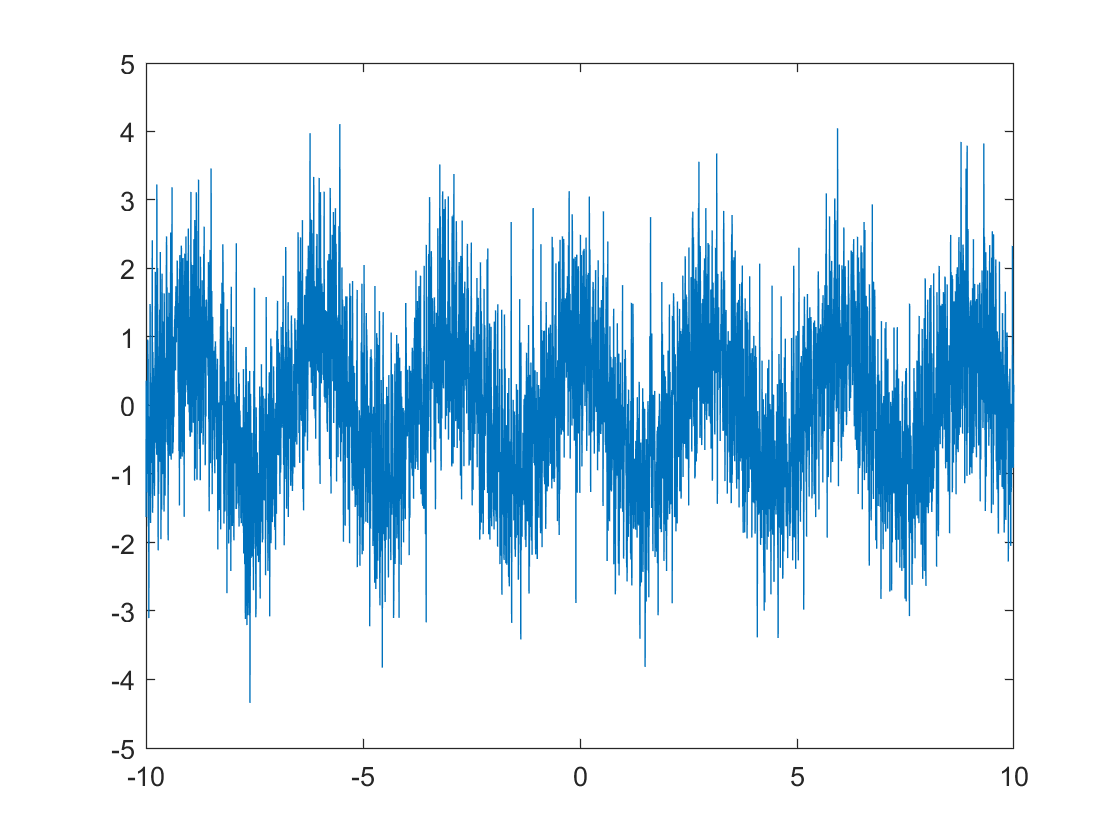

% some other plots for comparison
plot(n, x3 + v) % the ideal plot w/ noise

plot(n, x1 + x2 + x3) % the output plot without filtering x3

A high pass filter is not ideal for this application given that the gaussian noise exists at all frequencies. This means we are still letting through the majority of the noise along with x3. That being said, you can still see the sine wave at the correct frequency and amplitude in the output plot. However, the signal to noise ratio is poor so it is hard to see.

#### Part C) Use Hamming, Blackman, and kaiser windows to extract x1.

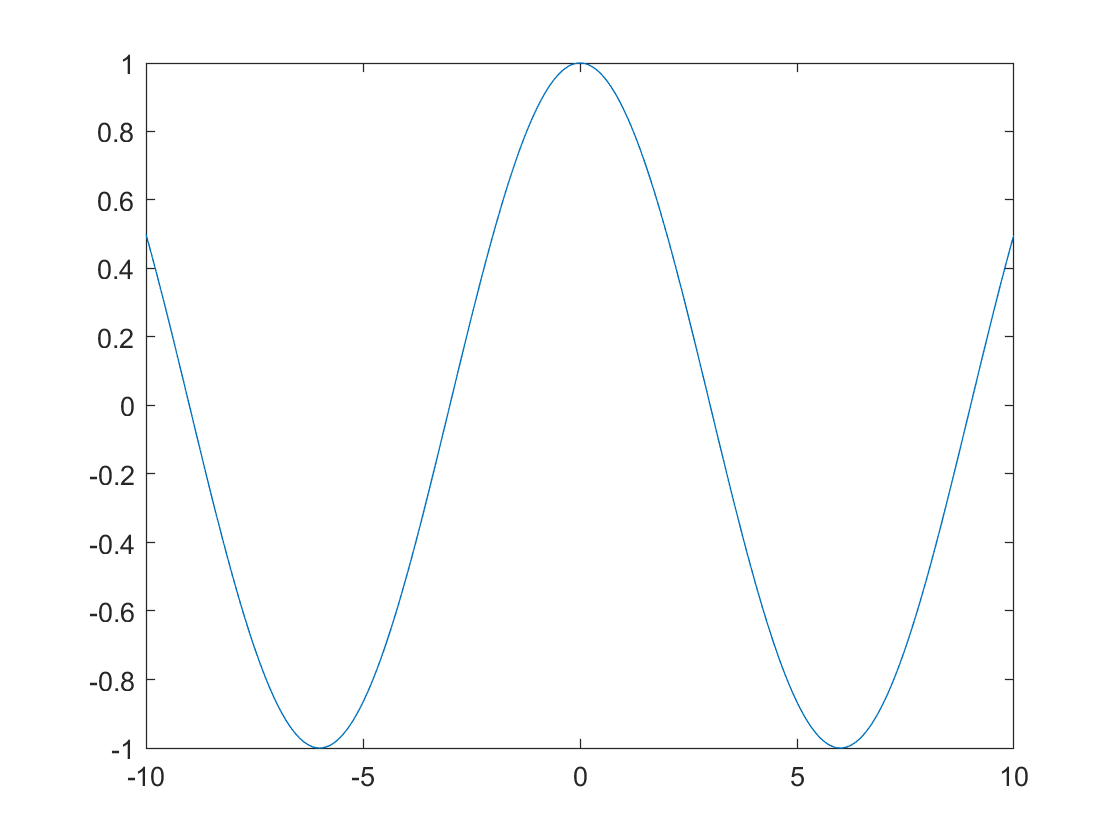

% lets begin by getting a good idea of what x1 looks like:
T = 0.005;
Fs = 1/T;
n = -10:T:10-T;
f = (Fs*(0:length(n)-1)/length(n));
plot(n, x1) % x1 in the time domain

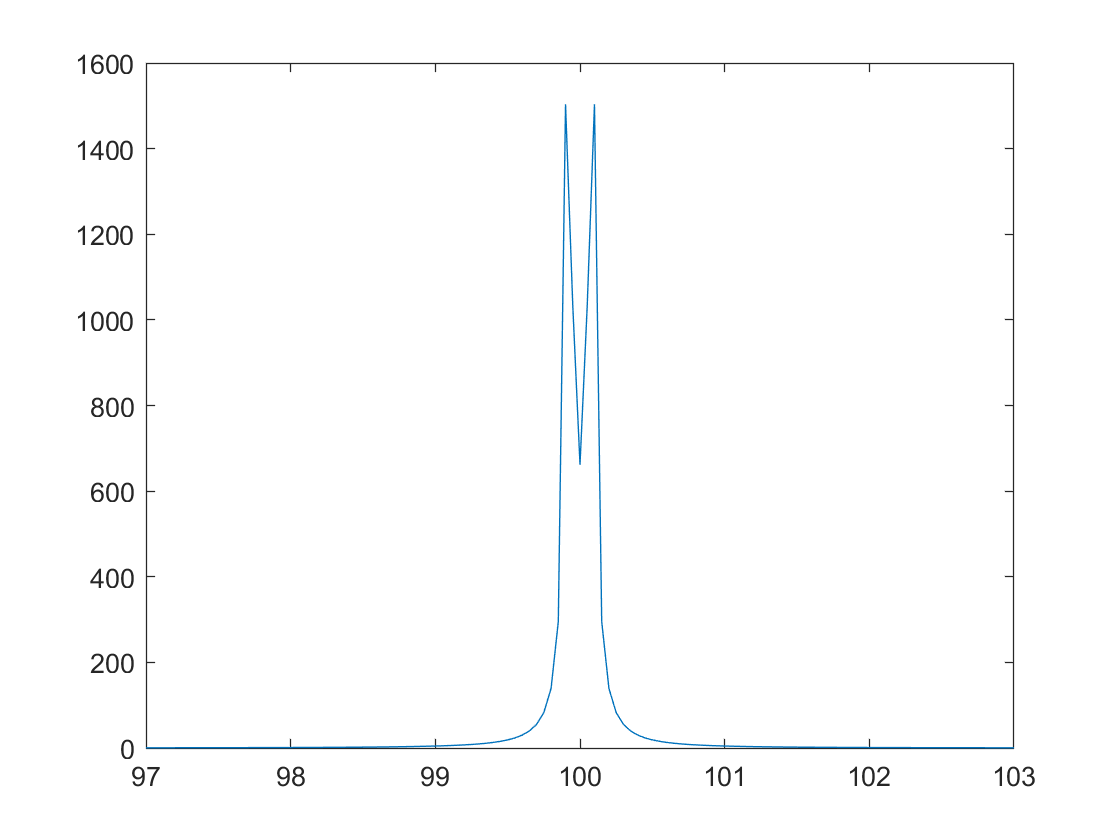

plot(f, abs(fftshift(fft(x1)))) %x1 in the frequency domain
xlim([100-3,100+3])

Next, let's extract x1 using a hamming window

% figure out the filter's parameters
wp = (2)*atan((pi/6)*T/2)

wp = 0.0026

ws = (2)*atan((pi/4)*T/2)

ws = 0.0039

wc = (wp + ws) / 2

wc = 0.0033

% we can approximate the window length as M = 8*pi/wc
M = 8*pi / wc

M = 7.6800e+03

%n = 0:T:M*T - T;
f = (Fs*(0:length(n)-1)/length(n));

%make the filter
b = fir1(2000,wp,"low"); % creates a low pass hamming filter
% convert to normal frequency range
[H,w] = freqz(b,1,length(f)/2);
H = H'

H =    1.0000 + 0.0000i   0.0000 + 1.0012i  -0.9945 - 0.0000i   0.0000 - 0.9438i   0.8018 + 0.0000i   0.0000 + 0.5638i  -0.3006 + 0.0000i  -0.0000 - 0.1068i   0.0186 - 0.0000i  -0.0000 - 0.0007i   0.0013 + 0.0000i   0.0000 + 0.0017i   0.0000 - 0.0000i   0.0000 + 0.0020i  -0.0002 - 0.0000i  -0.0000 + 0.0019i  -0.0002 + 0.0000i  -0.0000 + 0.0017i  -0.0002 + 0.0000i   0.0000 + 0.0015i  -0.0001 + 0.0000i  -0.0000 + 0.0014i  -0.0001 + 0.0000i   0.0000 + 0.0013i  -0.0001 - 0.0000i   0.0000 + 0.0012i  -0.0001 - 0.0000i  -0.0000 + 0.0011i  -0.0001 - 0.0000i  -0.0000 + 0.0010i  -0.0001 + 0.0000i   0.0000 + 0.0010i  -0.0001 - 0.0000i   0.0000 + 0.0009i  -0.0000 - 0.0000i   0.0000 + 0.0009i  -0.0000 + 0.0000i   0.0000 + 0.0008i  -0.0000 - 0.0000i  -0.0000 + 0.0008i  -0.0000 - 0.0000i   0.0000 + 0.0007i  -0.0000 + 0.0000i   0.0000 + 0.0007i  -0.0000 + 0.0000i   0.0000 + 0.0007i  -0.0000 - 0.0000i   0.0000 + 0.0006i  -0.0000 - 0.0000i  -0.0000 + 0.0006i


% flip and append H so it covers the negative part of the frequency domain too
H = fftshift([fliplr(H) H]/max(H))

H =    0.0000 - 0.9988i   1.0000 + 0.0000i  -0.0000 + 0.9933i  -0.9427 - 0.0000i   0.0000 - 0.8008i   0.5631 - 0.0000i   0.0000 + 0.3002i  -0.1067 + 0.0000i  -0.0000 - 0.0185i  -0.0007 + 0.0000i   0.0000 - 0.0013i   0.0017 - 0.0000i  -0.0000 - 0.0000i   0.0020 - 0.0000i  -0.0000 + 0.0002i   0.0019 + 0.0000i   0.0000 + 0.0002i   0.0017 + 0.0000i   0.0000 + 0.0002i   0.0015 - 0.0000i   0.0000 + 0.0001i   0.0014 + 0.0000i   0.0000 + 0.0001i   0.0013 - 0.0000i  -0.0000 + 0.0001i   0.0012 - 0.0000i  -0.0000 + 0.0001i   0.0011 + 0.0000i  -0.0000 + 0.0001i   0.0010 + 0.0000i   0.0000 + 0.0001i   0.0010 - 0.0000i  -0.0000 + 0.0001i   0.0009 - 0.0000i  -0.0000 + 0.0000i   0.0009 - 0.0000i   0.0000 + 0.0000i   0.0008 - 0.0000i  -0.0000 + 0.0000i   0.0008 + 0.0000i  -0.0000 + 0.0000i   0.0007 - 0.0000i   0.0000 + 0.0000i   0.0007 - 0.0000i   0.0000 + 0.0000i   0.0007 - 0.0000i  -0.0000 + 0.0000i   0.0006 - 0.0000i  -0.0000 + 0.0000i   0.0006 + 0.0000i


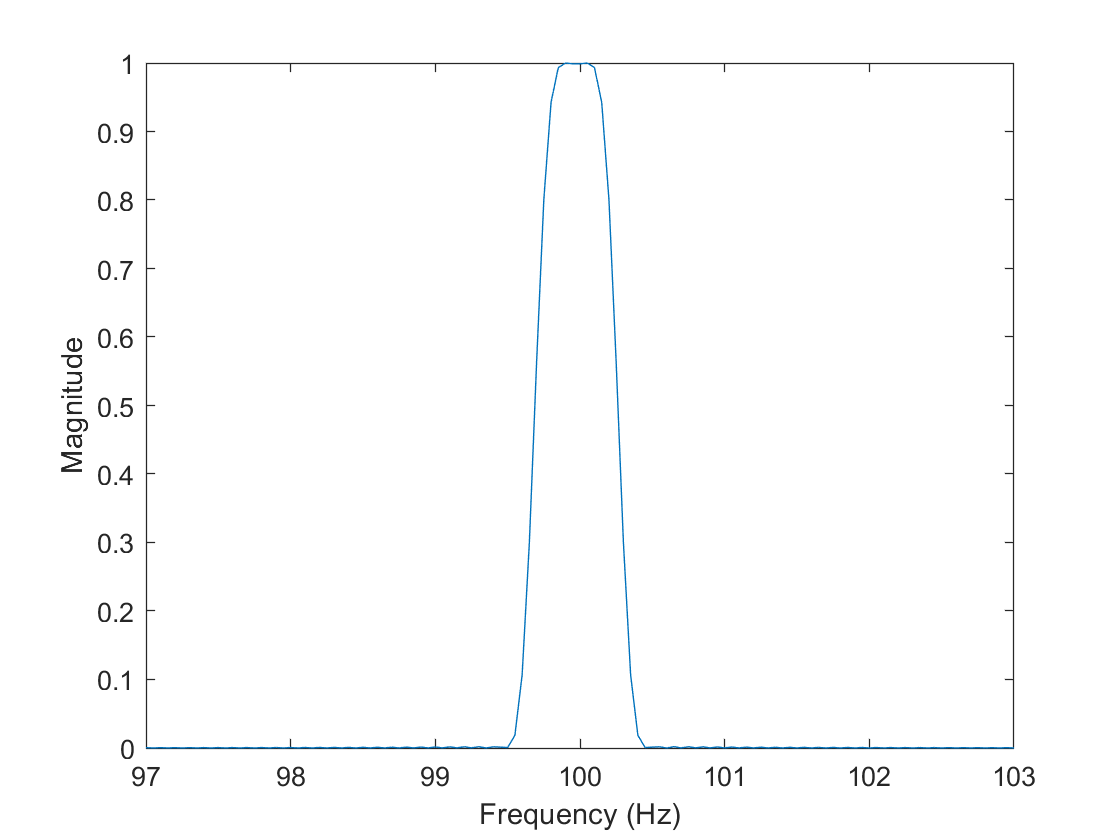


% plot the resulting filter
plot(f, abs(fftshift(H)))
xlabel 'Frequency (Hz)', ylabel 'Magnitude'
xlim([100-3, 100+3])

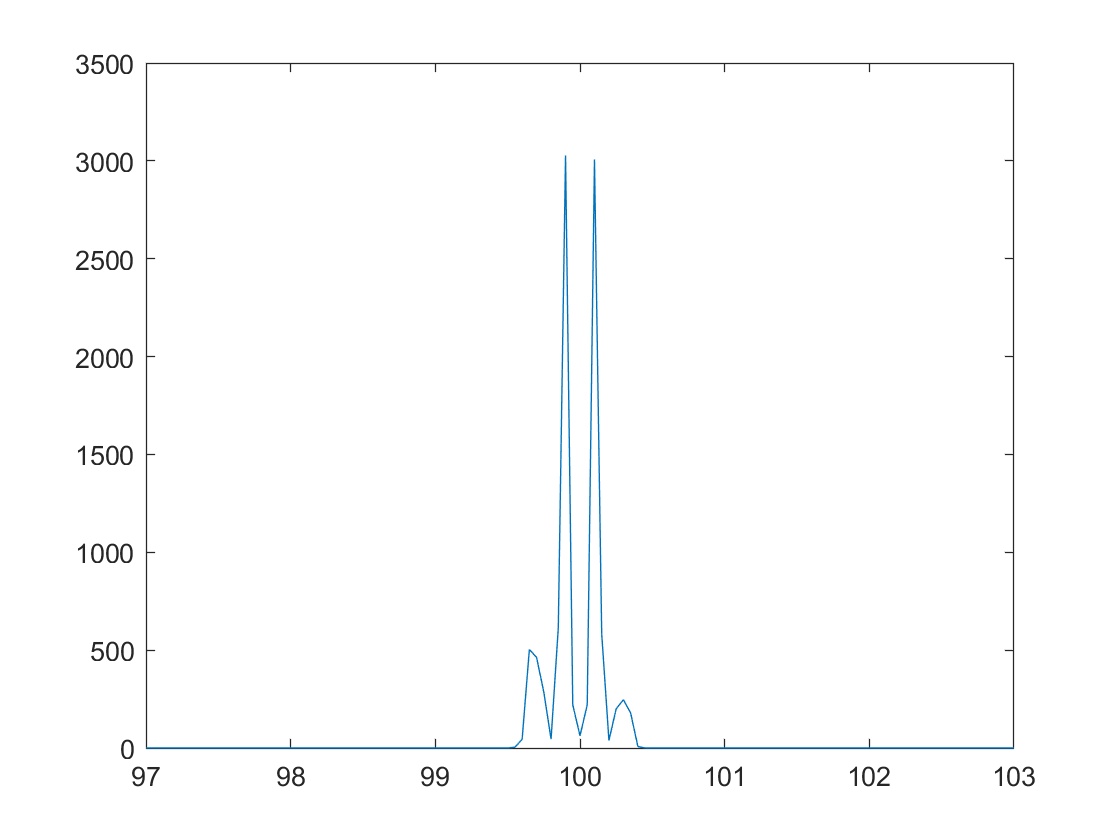


% now apply the filter to our input signal
Y = H .* X;
plot(f, abs(fftshift(Y)))
xlim([100-3, 100+3])

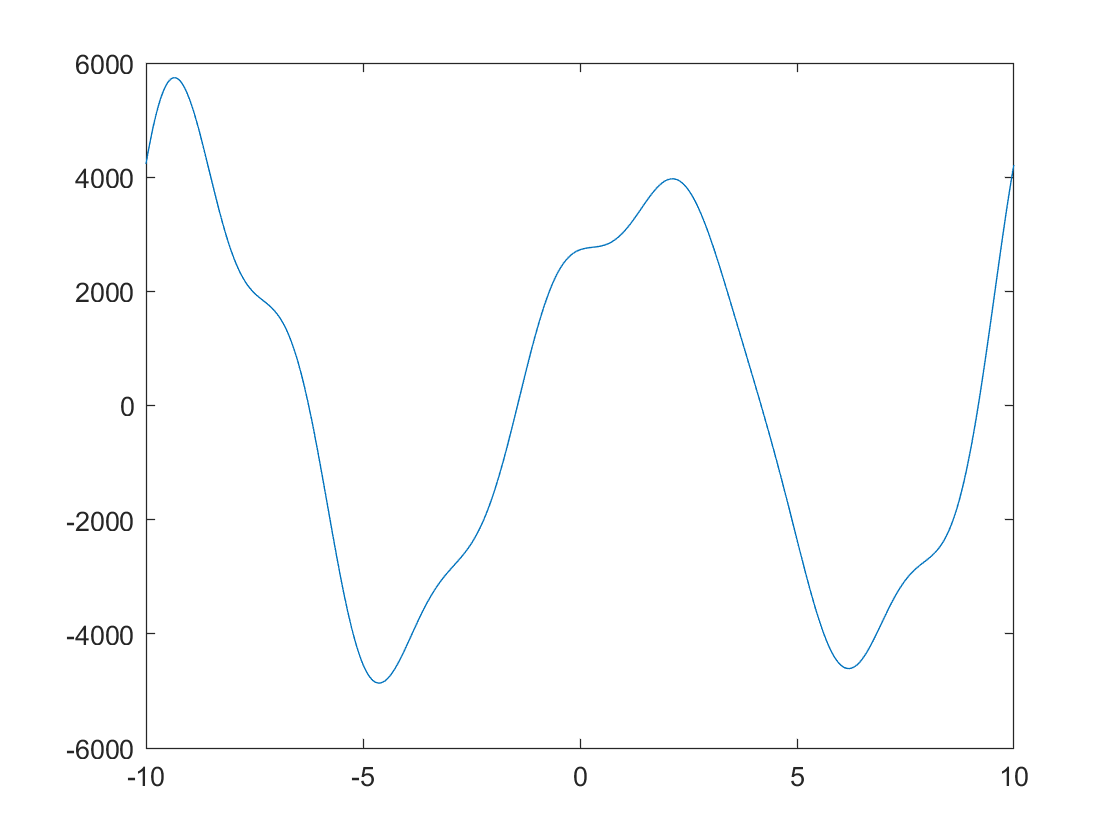


%plot the output signal in the time domain
y = real(fft(Y));
plot(n, y)

%compare that to the ideal signal
plot(n, x1)

This filter does a relatively good job of recovering x1 while ignoring x2, x3, and the noise. You can still see some of x2 in the signal since that signal's frequency is so close to x1's.

No lets extract x1 using a blackman window

% figure out the filter's parameters
n = -10:T:10-T;
wp = (2)*atan((pi/6)*T/2)

wp = 0.0026

ws = (2)*atan((pi/4)*T/2)

ws = 0.0039

wc = (wp + ws) / 2

wc = 0.0033

% we can approximate the window length as M = 8*pi/wc
M = 8*pi / wc

M = 7.6800e+03

alpha = (M-1)/2

alpha = 3.8395e+03

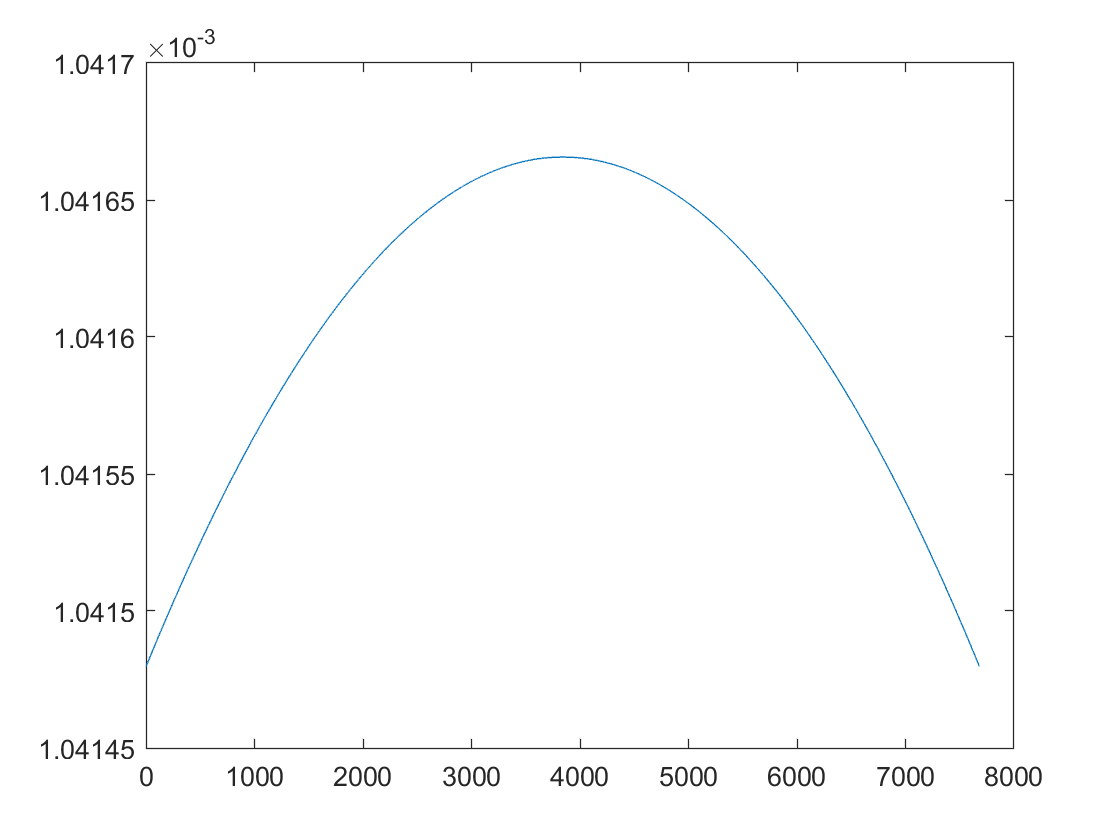



% desired low pass filter
nhd = -10:20/M:10 - 20/M;
hd = (sin(wc*(nhd)))./(pi*(nhd));
plot(hd)

% blackman window
wb = blackman(M);

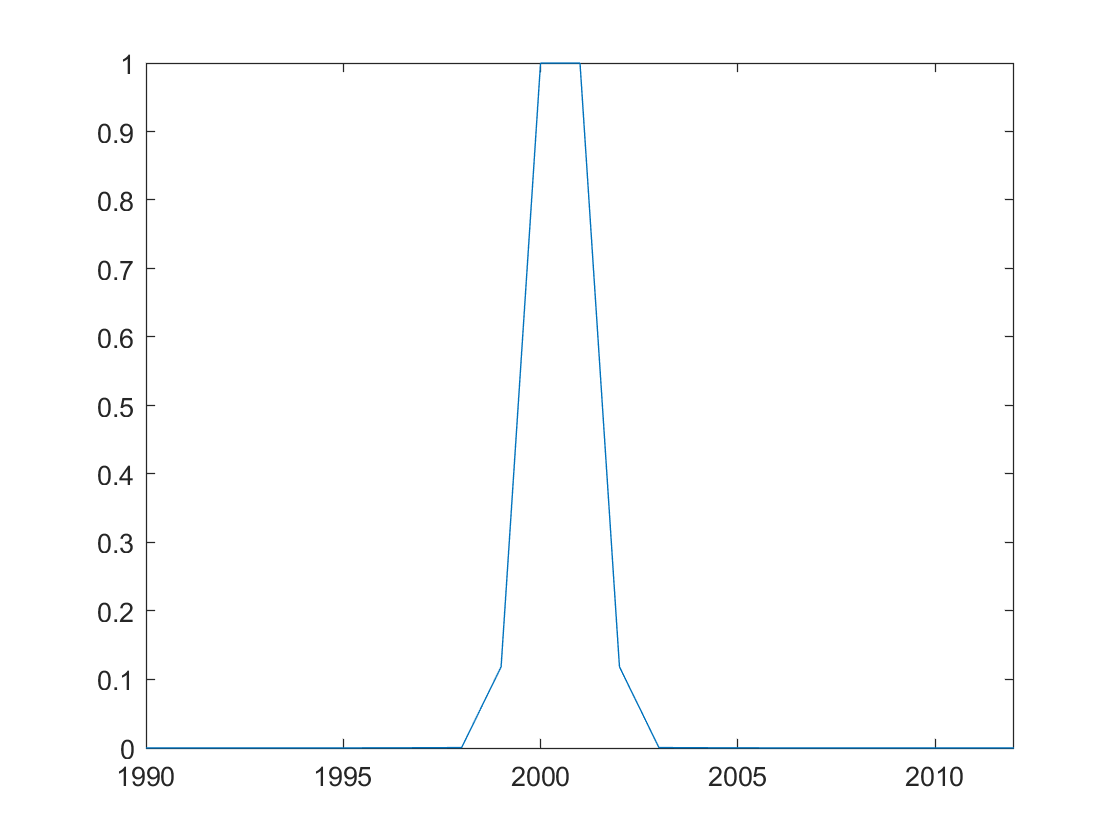

% new blackman low pass filter
hn = wb' .* hd;
% convert to frequency domain
H = freqz(hn,1,length(n)/2);
%convert the filter from the z domain to the frequency domain
H = H';
H = fftshift([fliplr(H) H]/max(H));

% plot the filter
plot(fftshift(abs(H)))
xlim([2001-11,2001+11])

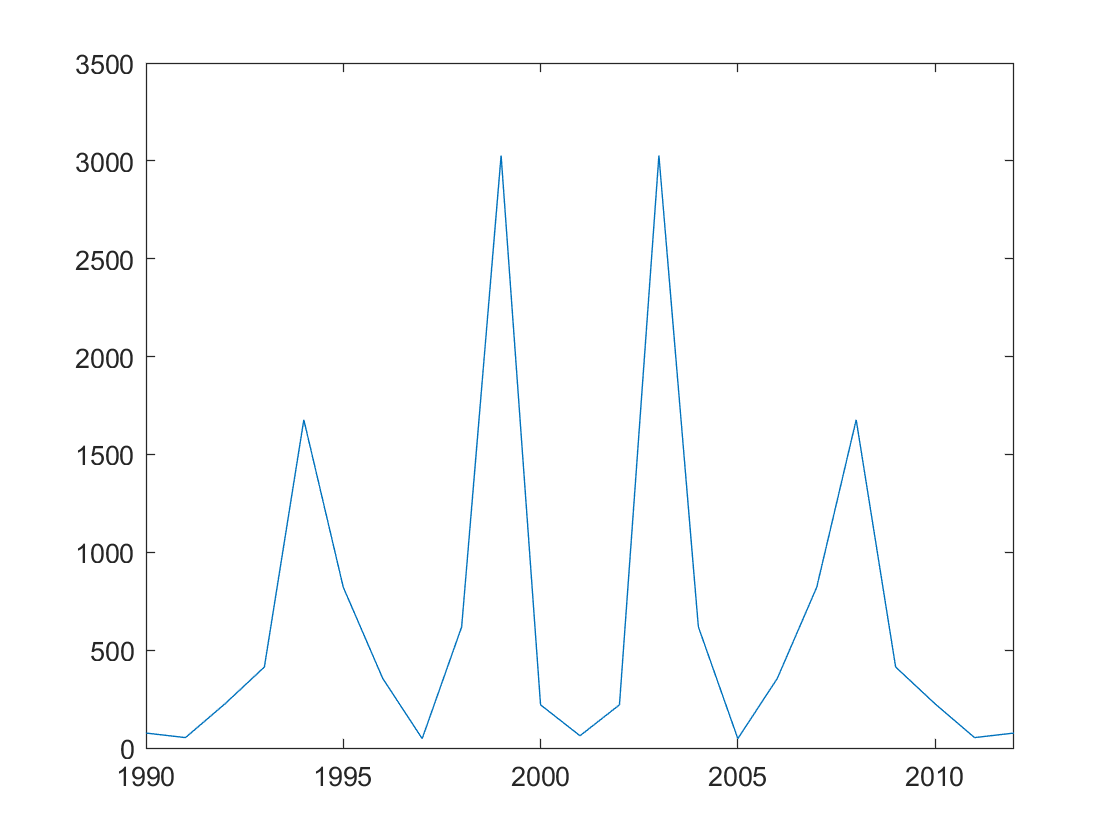


% apply the filter
Y = H .* X;
% see the frequency domain result
plot(abs(fftshift(X)))
xlim([2001-11,2001+11])

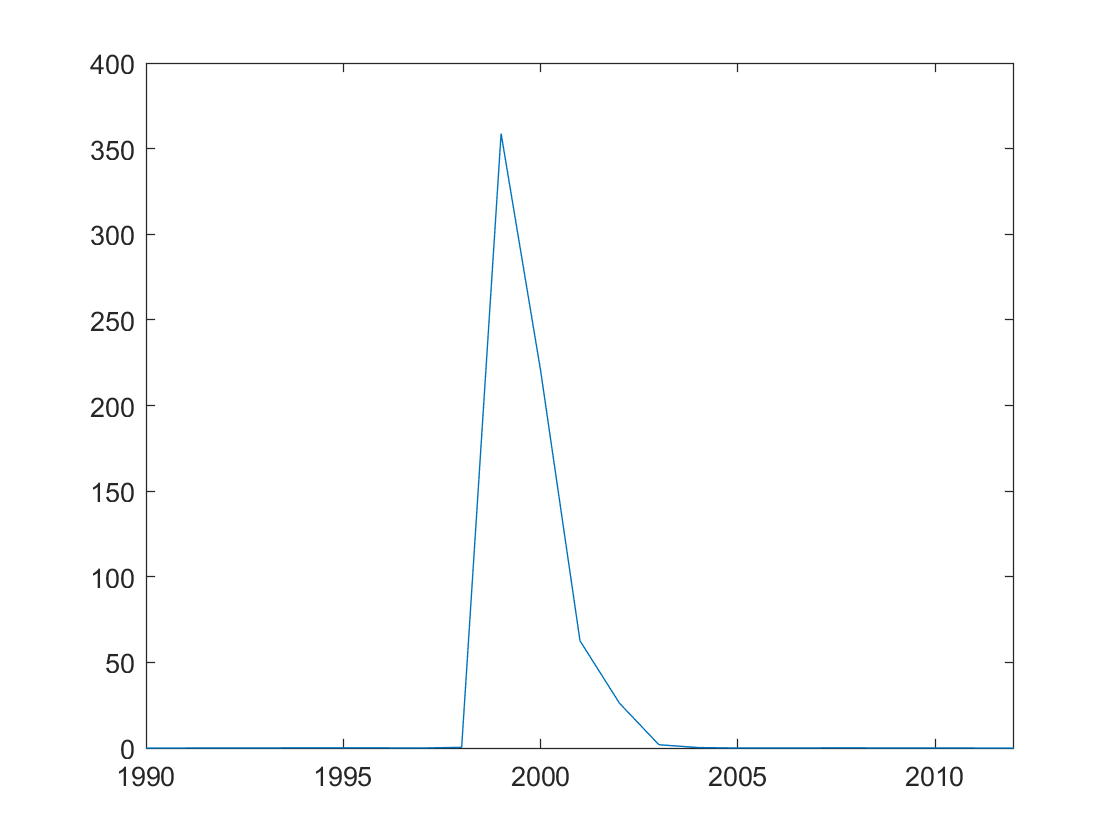

plot(abs(fftshift(Y)))
xlim([2001-11,2001+11])

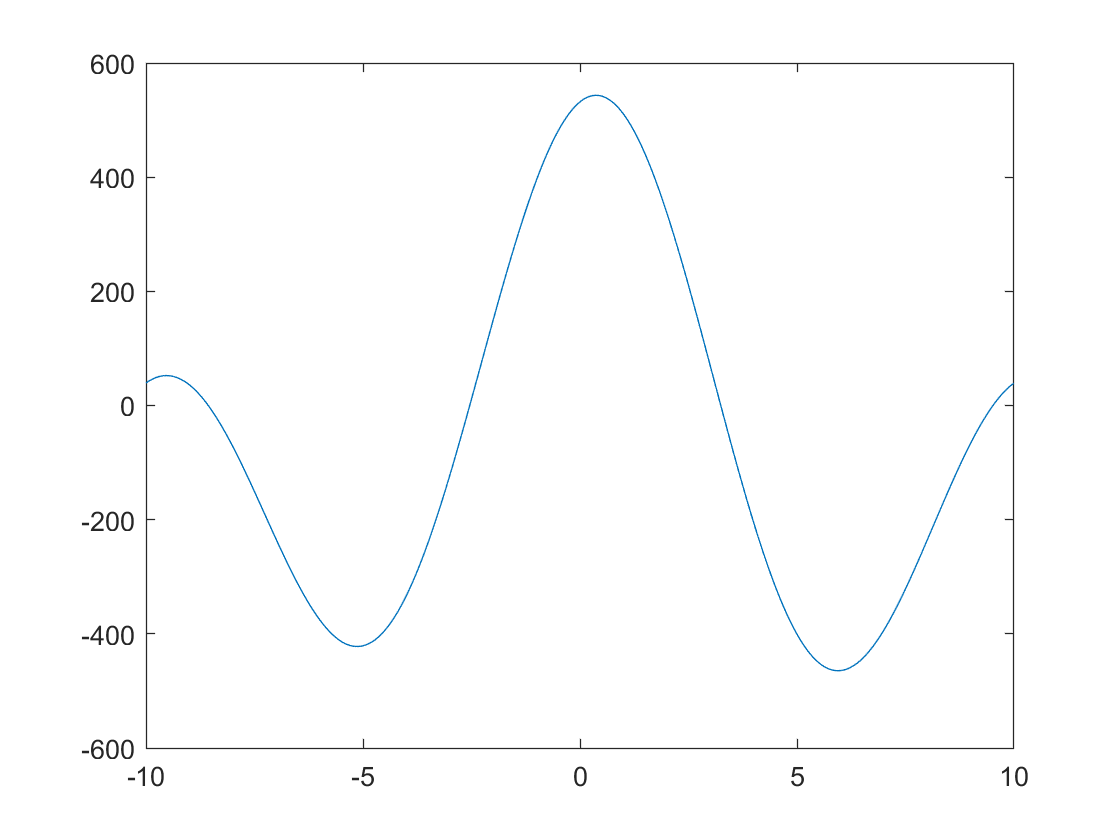


% plot the output and compare it to the ideal output
y = real(fft(Y));
plot(n, y)

%compare that to the ideal signal
plot(n, x1)

This blackman filter does an okay job of extracting x1 from the signal. It doesn't have the issues that the hamming filter had where some of x2 can also be seen. Instead, there is a little bit of an asymetry that was produced due to the filter transferr function being centered at 2000.5, while the function X is centered at 2001.

Finally, lets extract x1 using a kaiser window

% figure out the filter's parameters
n = -10:T:10-T;
wp = (2)*atan((pi/6)*T/2)

wp = 0.0026

ws = (2)*atan((pi/4)*T/2)

ws = 0.0039

wc = pi*12.5/25%(wp + ws) / 2 +0.01

wc = 1.5708

% we can approximate the window length as M = 8*pi/wc
M = length(n)%8*pi / wc

M = 4000

alpha = (M-1)/2

alpha = 1.9995e+03

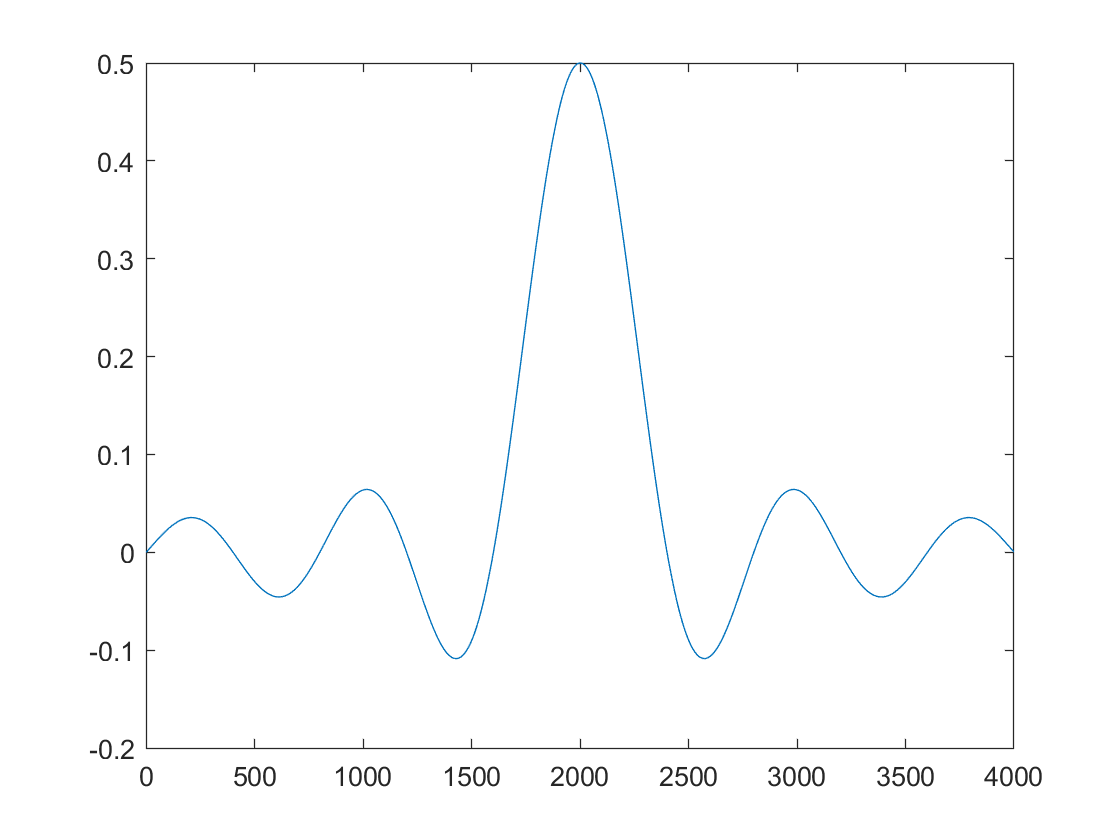



% desired low pass filter
nhd = -10:20/M:10 - 20/M;
hd = (sin(wc*(nhd)))./(pi*(nhd));
plot(hd)

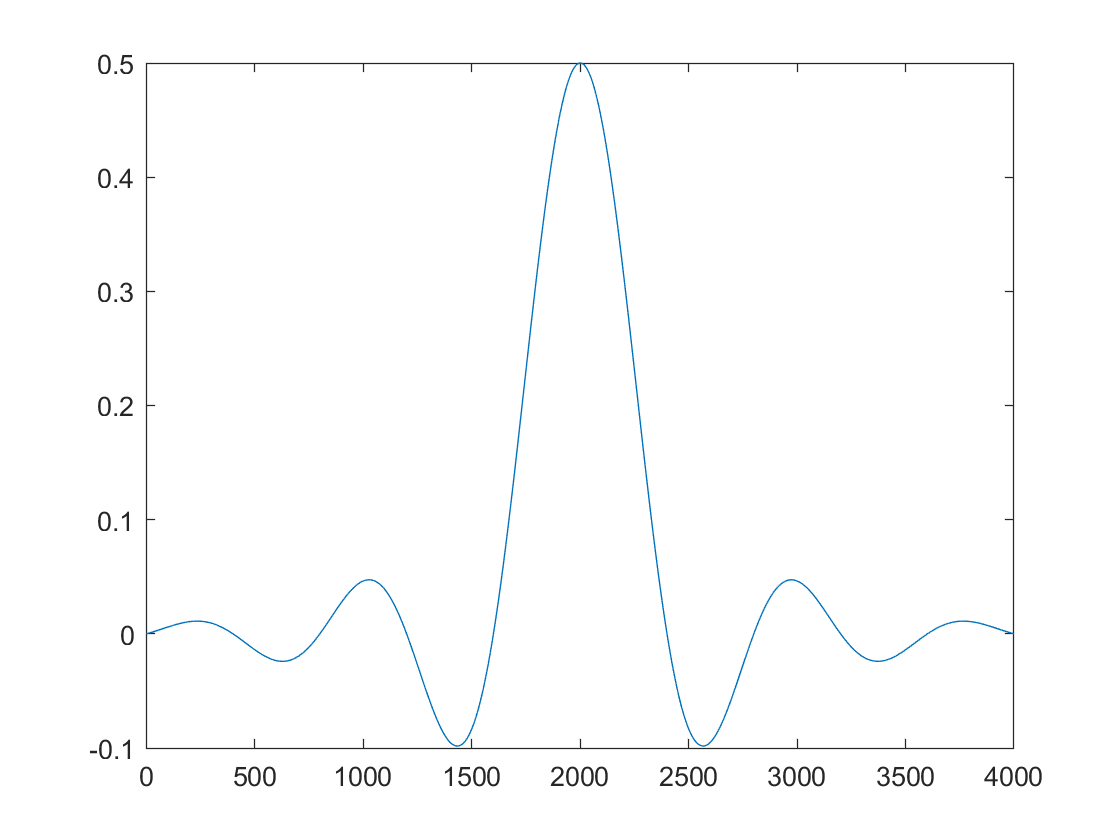

% blackman window
wb = kaiser(M, 3);
% new blackman low pass filter
hn = wb' .* hd;
plot(hn)

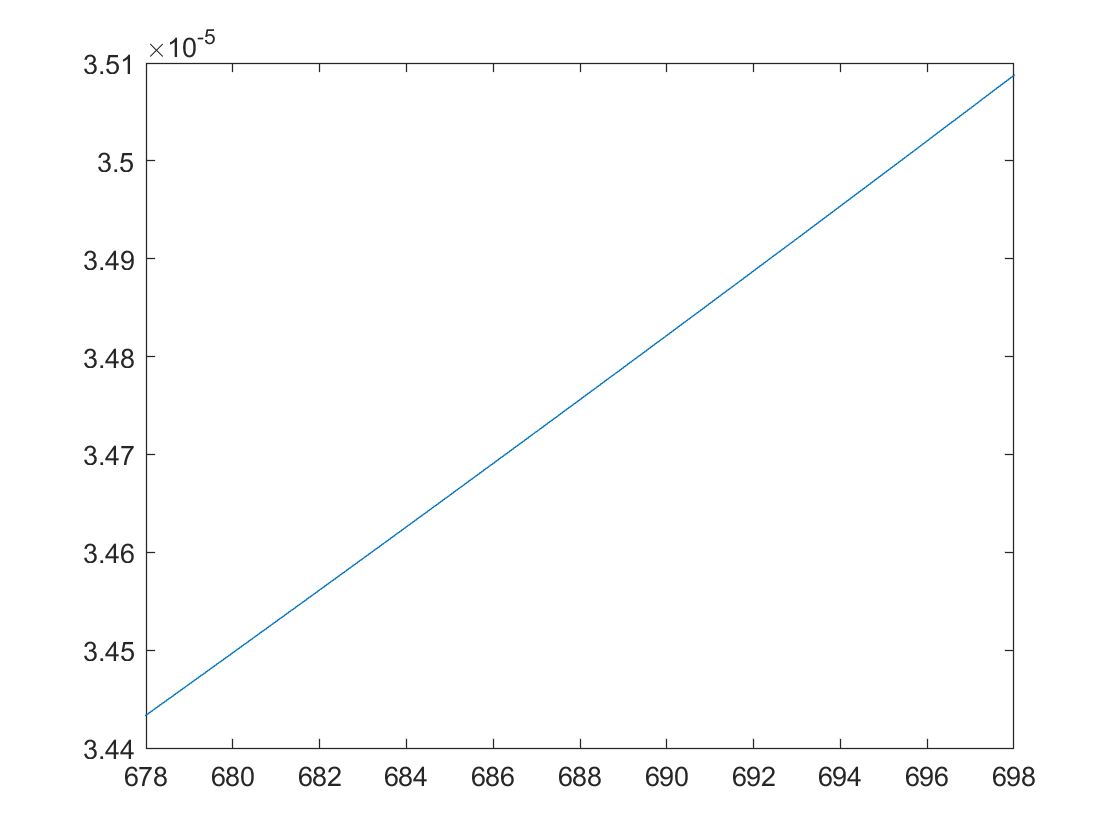

plot(abs(fftshift(fft(hn))))
xlim([688-10, 688+10])

% convert to frequency domain
H = freqz(hn,1,length(n)/2);
%convert the filter from the z domain to the frequency domain
H = H';
H = fftshift([fliplr(H) H]/max(H));

hn = fft(hn)

hn = 	1.0e+02 *

   2.0155 + 0.0000i  -1.9841 + 0.0000i   2.0171 + 0.0000i  -1.9823 + 0.0000i   1.9740 + 0.0001i  -0.9959 - 0.0003i   0.0342 + 0.0001i  -0.0092 + 0.0000i  -0.0082 + 0.0000i  -0.0064 + 0.0000i  -0.0050 + 0.0000i  -0.0040 + 0.0000i  -0.0033 + 0.0000i  -0.0028 + 0.0000i  -0.0023 + 0.0000i  -0.0020 + 0.0000i  -0.0018 + 0.0000i  -0.0015 + 0.0000i  -0.0014 + 0.0000i  -0.0012 + 0.0000i  -0.0011 + 0.0000i  -0.0010 + 0.0000i  -0.0009 + 0.0000i  -0.0008 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i


hn = hn / max(hn)

hn =    0.9992 - 0.0000i  -0.9837 + 0.0000i   1.0000 + 0.0000i  -0.9828 + 0.0000i   0.9787 + 0.0000i  -0.4937 - 0.0001i   0.0169 + 0.0000i  -0.0046 + 0.0000i  -0.0041 + 0.0000i  -0.0032 + 0.0000i  -0.0025 + 0.0000i  -0.0020 + 0.0000i  -0.0016 + 0.0000i  -0.0014 + 0.0000i  -0.0012 + 0.0000i  -0.0010 + 0.0000i  -0.0009 + 0.0000i  -0.0008 + 0.0000i  -0.0007 + 0.0000i  -0.0006 + 0.0000i  -0.0005 + 0.0000i  -0.0005 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i


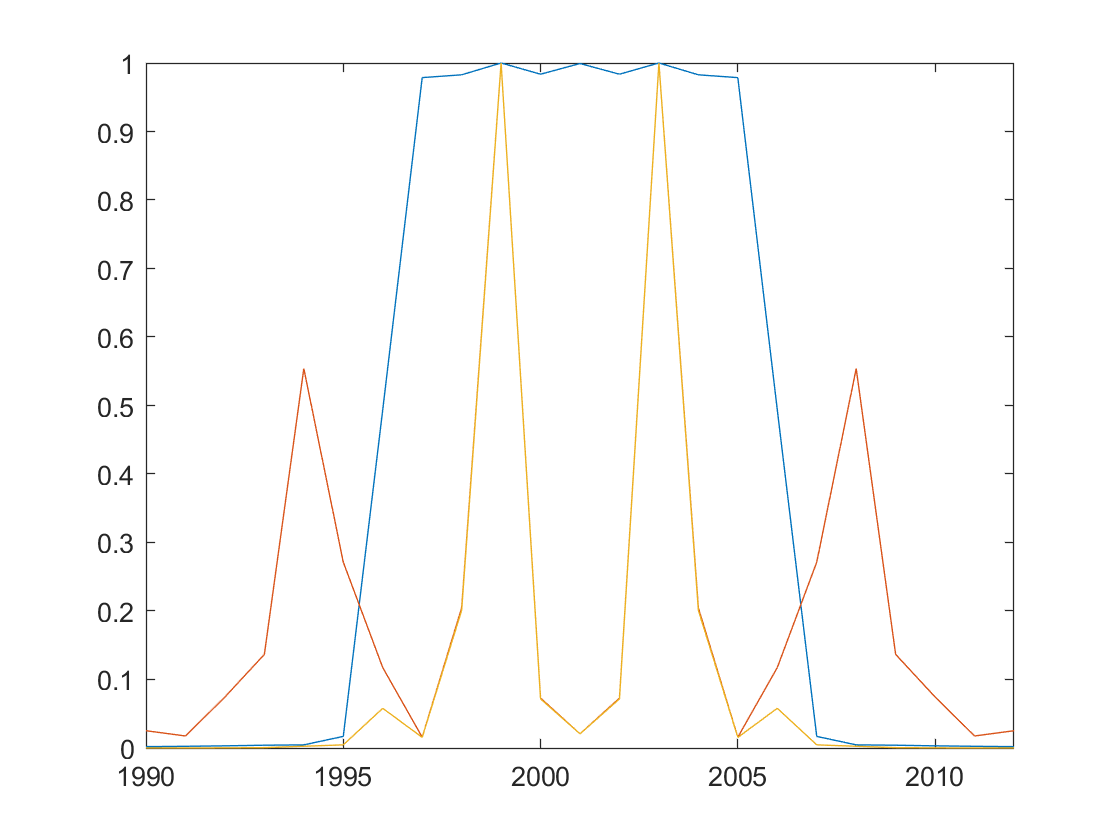

% plot the filter
plot(abs(fftshift((hn))))
xlim([2001-11,2001+11])

% apply the filter
Y = hn .* X;
% see the frequency domain result
hold("on")
plot(abs(fftshift(X)) / max(abs(X)))
xlim([2001-11,2001+11])
plot(abs(fftshift(Y)) /max(abs(Y)))
xlim([2001-11,2001+11])
hold("off")

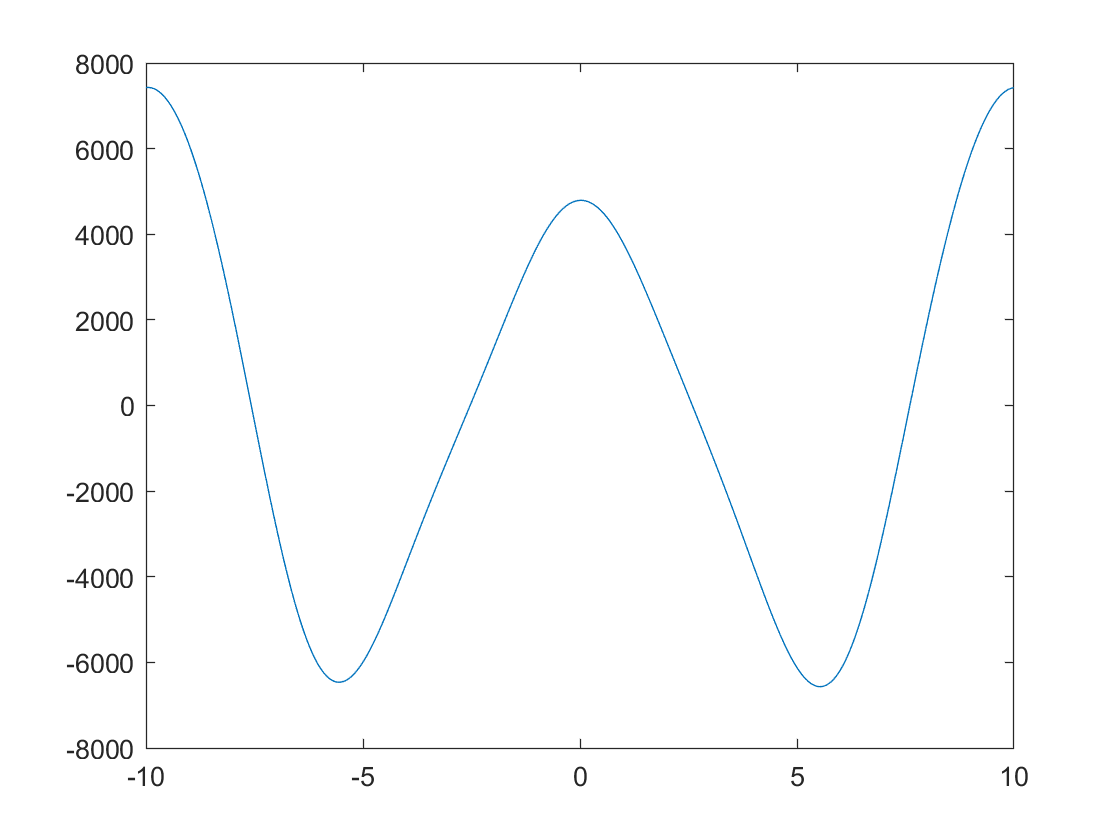


% plot the output and compare it to the ideal output
y = real(fft(Y));
plot(n, y)


%compare that to the ideal signal
plot(n, x1)

This filter also does a relatively good job of getting rid of x2 and x3 while leaving x1 relatively intact.

#### Part D) Use an elliptic, butterworth or chebyshev filter to extract x1

% normalized cutoff frequency

wp = 0.0031

ws = 0.0039

wc = 0.225/(Fs/2)

wc = 0.0023


% create a bbutterworth transfer function
[b,a] = butter(6,wc);

% plot the transfer function magnitude and phase
[h,w] = freqz(b,a,[],Fs)

h =    1.0187 + 0.0000i
  -0.6874 + 0.6012i
   0.0252 - 0.0264i
  -0.0002 - 0.0032i
  -0.0002 - 0.0005i
  -0.0001 - 0.0001i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


w =          0
    0.1953
    0.3906
    0.5859
    0.7812
    0.9766
    1.1719
    1.3672
    1.5625
    1.7578


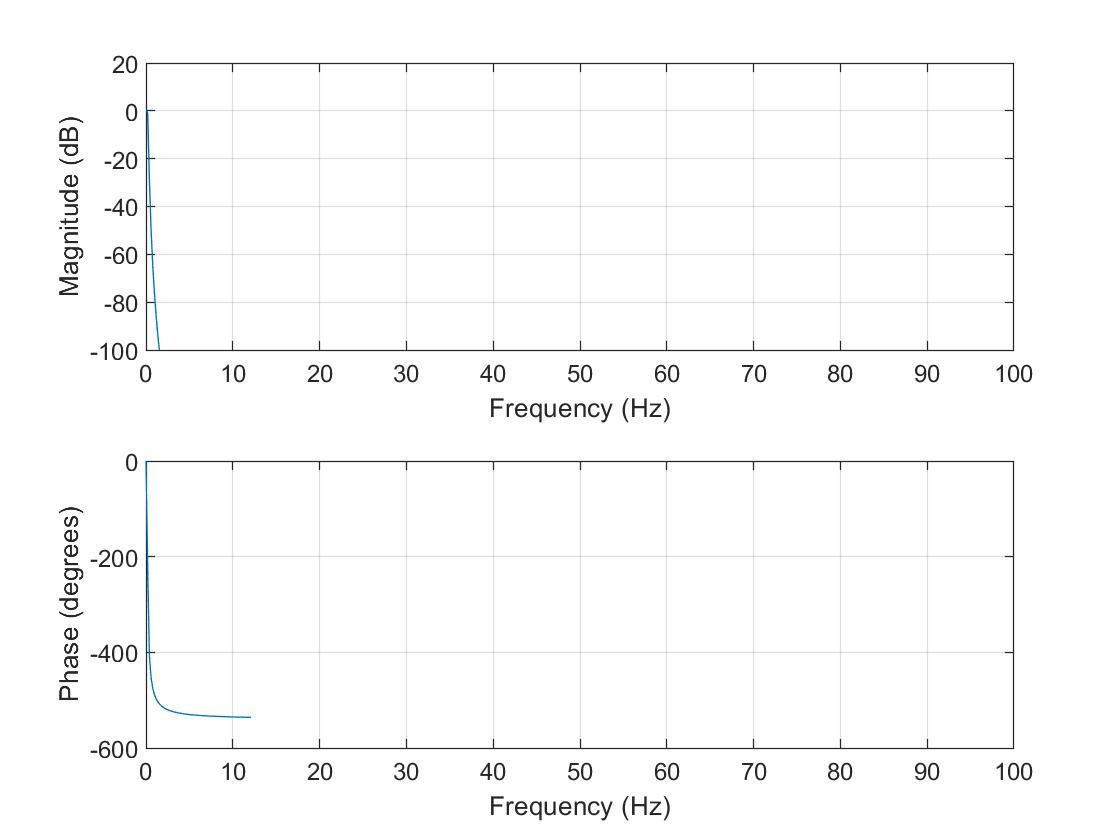

freqz(b,a,[],Fs)
subplot(2,1,1)
ylim([-100 20]);

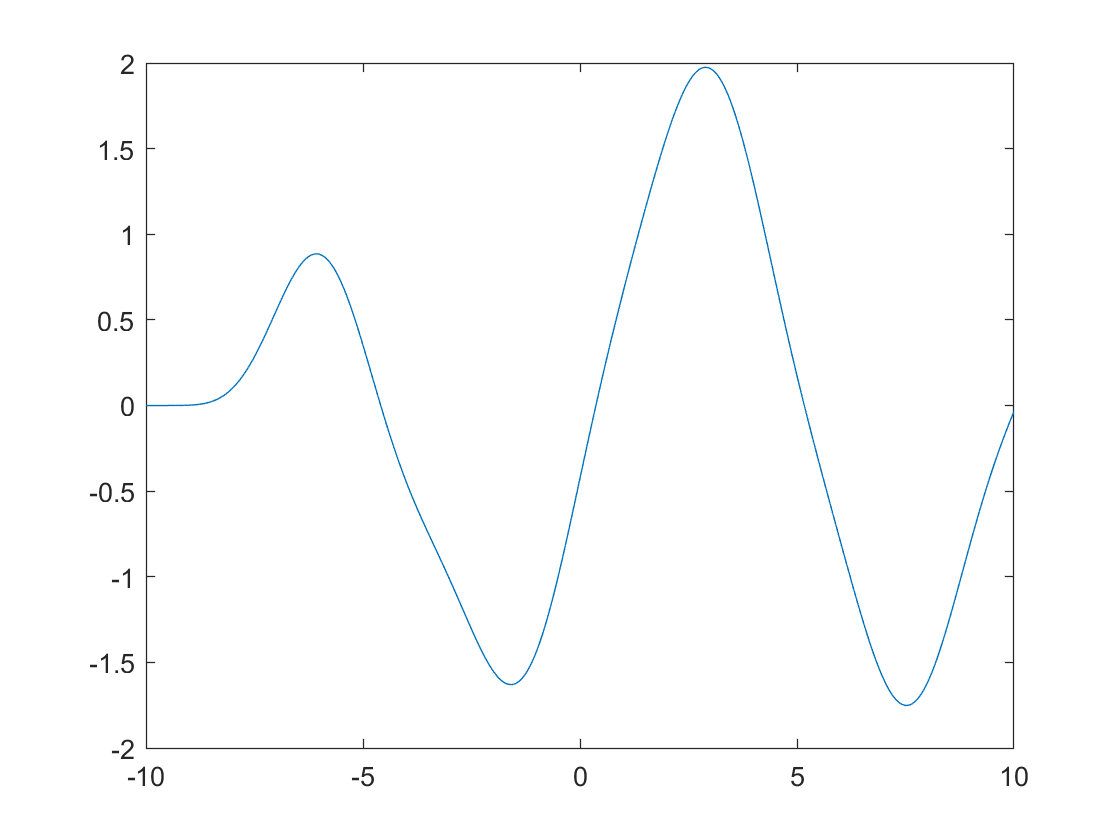

figure;

% filter the input signal with the transfer function
y = filter(b,a,x);
% plot the filtered signal
plot(n,y)

% plot the ideal signal
plot(n,x1)

The filter takes a little bit of time to take effect and become accuract. This can be seen at time between -10 and 0. However, after that, the filter is very accuracte and perfectly recovers the input signal x1. (with a little phase shift)